# Model Creation

## Loading preprocessed datasets

clear
load preProcessedData.mat


## Creating DataSets

Dropping unwanted variables (you can change between normalized and unnormalized(filled) data here)

reducedData = filledData_234(:,[10:24, 3349:end, 4]); %data without patterns
fullData = filledData_234(:,[10:end, 4]);

## Choosing DataSet

finalData = fullData

### Splitting the data

rng(1); %random number generated seed for reproducability so we always get the same test and training set in the future

partitions = cvpartition(finalData.note,'HoldOut',0.2); 
%splitting data for training and testing, this gives indices for each
%the first input ensures stratified sampling so that same proportions of target class are separated, this is important when the dataset is small or we have a class imbalance this way the test set will be a good representation of the whole data



finalDataTest = finalData(test(partitions),:);
finalDataTrain = finalData(training(partitions),:);


## Nomarlization 

(in case we used filledData)

(run only once)

%normalize data to make sure all features have the same scale
%KNN and SVM are sensitive to the scaling of features

mean = mean(finalDataTrain{:,1:end-1}); %save this so it can be applied on the test data
std = std(finalDataTrain{:,1:end-1}); %save this so it can be applied on the test data

finalDataTrain{:,1:end-1} = (finalDataTrain{:,1:end-1} - mean) ./ std; %z-score normalization
finalDataTest{:,1:end-1} = (finalDataTest{:,1:end-1} - mean) ./ std;

## Feature Selection

- this part is only for when the fullData is used (not reducedData)

Initial reduction step: 

### filter method

Wrapper methods involve training multiple models with different combinations of predictors, so they can be computationally intensive. If you have a high-dimensional dataset, you may want to initially reduce the number of features with a method that's less computationally intensive like a filter method.

Since this is a classification problem, a suitable choice for a filter method is minimum redundancy maximum relevance (MRMR) algorithm

[idx,score] = fscmrmr(finalDataTrain(:,1:end-1),finalDataTrain.note)

idx =         3273        3058        1595        1886        2127        1210         699        1185        1396        2457        3114        1029        2697        2884        1899         806        3258        2853        2951        2496        1810        3077        3012         427        2393        2167        2492        1769        1414         901        3154        2900        2376        2560        2995        2442        1873        3332        3345        2297        1354        2962        3019        1548        2054        2692        2621        2845         457        2983


score =          0         0    0.0000    0.0000    0.0004    0.0000    0.0003    0.0003    0.0001    0.0003    0.0004    0.0008         0    0.0017         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


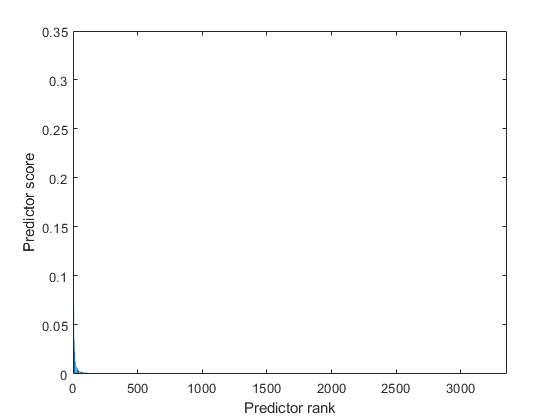

%idx shows the indices of the predictors that explain the response variability the most, in that order

bar(score(idx))
xlabel('Predictor rank')
ylabel('Predictor score')

let's try the top 500 features to see how the wrapper method performs. This should reduce the training time for each model while still providing enough features for the wrapper method to choose from.

finalDataTrainFilter = [finalDataTrain(:,idx(1:500)) finalDataTrain(:,end)]

finalDataTrainFilter = 341×501 table
    VEF_R53      APF_L15     AFE_L96     HPFEM_R90    KFEM_L34      KFE_R8      HPAA_R91    HPIE_L82     KFE_L95     HPP_R67      MLF_R12     HPIE_R25      KP_L10        AP_R98      HPFEM_L4    HPAA_L99     VEF_R38      AP_R67      AP_L66       HPP_L7     HPFEM_R14     APF_L34      APF_R28     PROTA_R17     HPP_R3      KFEM_L74      HPP_L3        AIE_L72      AFE_R14     HPFE_R95      MLF_R52      AP_L15     

### wrapper methods

feature selection by wrapper methods on a "wide" dataset. Feature selection methods will reduce the chance of training a model that overfits the data. They will also reduce the training time and make the model easier to interpret.

Sequential feature selection: Forward feature selection and Backward feature selection

we use `sequentialfs function, `first argument needs to be a function that trains a model and returns a single value that quantifies the model error

The function `KNNerror` is defined at the bottom of this script. It trains a KNN model and returns the misclassification rate. Notice the function name below is preceded by the "@" symbol. This creates a function handle that MATLAB uses to reference the function.

The output of `sequentialfs` is a logical vector that specifies which features to keep in the model.

%this process shows a random behaviour, its better not to use it in the end

%%%inModel = sequentialfs(@KNNerror,finalDataTrainFilter{:,1:end-1},finalDataTrainFilter.note, ...
%%%"direction","forward","cv",20)

%"direction" Allows you to select forward or backward feature selection. Use "forward" if you think only a few features are useful or "backward" otherwise
%"cv" - Allows you to specify the validation method


%%%nnz(inModel) % this shows the number of features that are selected

The last step is to make a new dataset by using the logical array.

%%%finalDataTrainWrapper = [finalDataTrainFilter(:,inModel) finalDataTrainFilter(:,end)]

## Model Fitting

rng(1)

%first choose which dataset you want to work with
myDataTrain = finalDataTrainFilter

myDataTrain = 341×501 table
    VEF_R53      APF_L15     AFE_L96     HPFEM_R90    KFEM_L34      KFE_R8      HPAA_R91    HPIE_L82     KFE_L95     HPP_R67      MLF_R12     HPIE_R25      KP_L10        AP_R98      HPFEM_L4    HPAA_L99     VEF_R38      AP_R67      AP_L66       HPP_L7     HPFEM_R14     APF_L34      APF_R28     PROTA_R17     HPP_R3      KFEM_L74      HPP_L3        AIE_L72      AFE_R14     HPFE_R95      MLF_R52      AP_L15     AFEM_L85


%To set model specific parameters, such as changing the kernel for an SVM model, create a template for the model you wish to use, Then pass the template to the fitcecoc function
%name value pairs for each tamplate are chosen after an optimization process using the app
%templateKNN templateSVM templateTree templateKernel templateLinear

templateknn = templateKNN('NumNeighbors',1,'Distance','cityblock','DistanceWeight','equal','Standardize', true);
templatesvm = templateSVM('KernelFunction', "polynomial",'PolynomialOrder',3,'BoxConstraint',1,'KernelScale','auto','Standardize', true); %'PolynomialOrder' can be used if you use polynomial kernel
templatetree = templateTree('MaxNumSplits',10,'SplitCriterion','gdi'); %'MinLeafSize',5
templatelinear = templateLinear('Learner','logistic','Regularization','ridge','OptimizeLearnRate','on');
templateBagEnsemble = templateEnsemble('Bag',30,templatetree); %better accuracy than normal tree, but longer training time
%templateKnnEnsemble = templateEnsemble('Subspace',30,'KNN'); %weak learner template is used here, not that good
templatenaivebayes = templateNaiveBayes();
templatediscriminant = templateDiscriminant('DiscrimType','diaglinear');

%The MATLAB function to train multiclass models is fitcecoc
mdl = fitcecoc(myDataTrain{:,1:end-1},myDataTrain.note,"Learners",templatediscriminant,"KFold",20) %"Coding","onevsone"

mdl =   classreg.learning.partition.ClassificationPartitionedECOC
    CrossValidatedModel: 'ECOC'
         PredictorNames: {1×500 cell}
           ResponseName: 'Y'
        NumObservations: 341
                  KFold: 20
              Partition: [1×1 cvpartition]
             ClassNames: [HEMI DX    HEMI SX    DIPLE]
         ScoreTransform: 'none'


  Properties, Methods


### prediction

[predictedNote, scores] = kfoldPredict(mdl);


### Confusion Matrix

%cMetrics functions are provided for simplicity
cMetrics(myDataTrain.note,predictedNote)

Accuracy = 83.58%

ans = 5×5 table
               Precision    Recall     Fallout     Specificity      F1   
               _________    _______    ________    ___________    _______

    HEMI DX     0.79389     0.86667     0.12217      0.87783      0.82869
    HEMI SX     0.87273     0.85714    0.061135      0.93886      0.86486
    DIPLE          0.85     0.77982    0.064655      0.93534       0.8134
    Avg         0.83887     0.83454    0.082654      0.91735      0.83565
    WgtAvg      0.83772     0.83578     0.08374      0.91626      0.83568


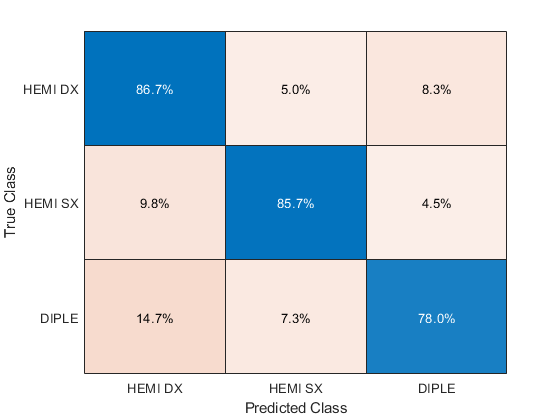


confusionchart(myDataTrain.note,predictedNote,"Normalization","row-normalized");

cm = confusionmat(myDataTrain.note,predictedNote);
accuracy = (cm (1,1) + cm (2,2) + cm (3,3)) / sum(sum(cm))*100

accuracy = 83.5777

### ROC curve

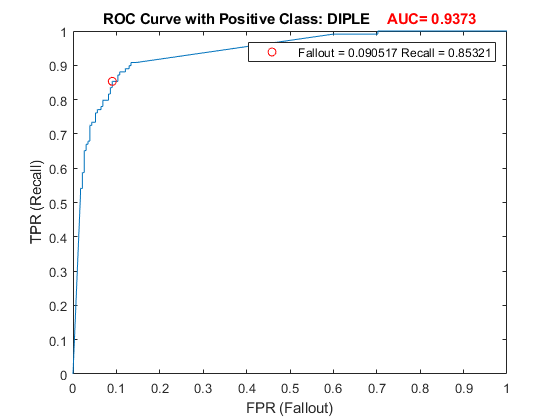

[fallouts,recalls,~,AUC,OPTROCPT] = perfcurve(myDataTrain.note,scores(:,3),"DIPLE"); %the number representing the column of scores depends on the ClassNames order in the model info
clf
plot(fallouts,recalls);
hold on
point = plot(OPTROCPT(1),OPTROCPT(2),"ro");
xlabel("FPR (Fallout)");
ylabel("TPR (Recall)");
title("ROC Curve with Positive Class: DIPLE"+"   \color{red} AUC= " +AUC)
legend(point, " Fallout = " + string(OPTROCPT(1)) + " Recall = " + string(OPTROCPT(2)) )
hold off

## Test Data Results

testPred = predict(mdl.Trained{2}, finalDataTest{:,idx(1:500)}); %the number of trained models corresponds to the number of folds in the training phase, any of the models can be used for test prediction here

cMetrics(finalDataTest.note,testPred)

Accuracy = 78.82%

ans = 5×5 table
               Precision    Recall     Fallout     Specificity      F1   
               _________    _______    ________    ___________    _______

    HEMI DX     0.81481     0.75862    0.089286      0.91071      0.78571
    HEMI SX         0.8     0.82759     0.10714      0.89286      0.81356
    DIPLE          0.75     0.77778     0.12069      0.87931      0.76364
    Avg         0.78827     0.78799     0.10571      0.89429      0.78764
    WgtAvg      0.78917     0.78824     0.10535      0.89465       0.7882


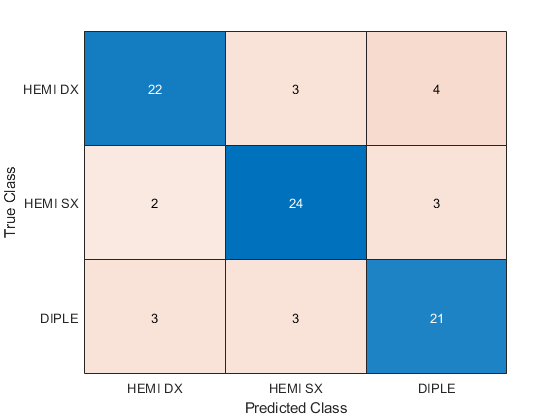


confusionchart(finalDataTest.note,testPred,"Normalization","absolute");

cm = confusionmat(finalDataTest.note,testPred);
accuracy = (cm (1,1) + cm (2,2) + cm (3,3)) / sum(sum(cm))*100

accuracy = 78.8235

## Local Functions

Error function (this is for wrapper feature selection)

%%%function error = KNNerror(XTrain,yTrain,XValidate,yValidate) 

    % Train a KNN model with the training data
%%%    mdl = fitcknn(XTrain,yTrain, ...
%%%        "NumNeighbors",3);
    
    % Calculate the error with the validation data
 %%%   yPredict = predict(mdl,XValidate);
 %%%   error = 1 - accuracy(yValidate,yPredict);
%%%end